clc;clear;close all;
image_o=imread("13-刘德华.jpg");

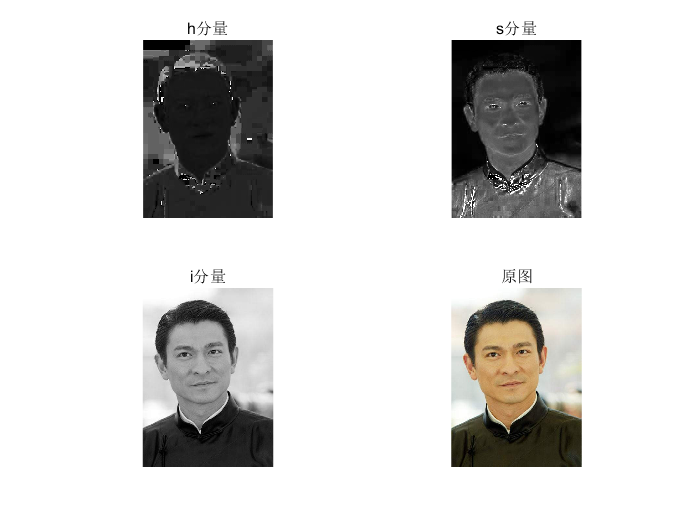

%转换得到图像的HSI分量，分别进行显示

im_hsi=rgb2hsi(image_o);

figure;
subplot(2,2,1);
imshow(im_hsi(:,:,1));
title("h分量");
subplot(2,2,2);
imshow(im_hsi(:,:,2));
title("s分量");
subplot(2,2,3);
imshow(im_hsi(:,:,3));
title("i分量");
subplot(2,2,4);
imshow(image_o);
title("原图");

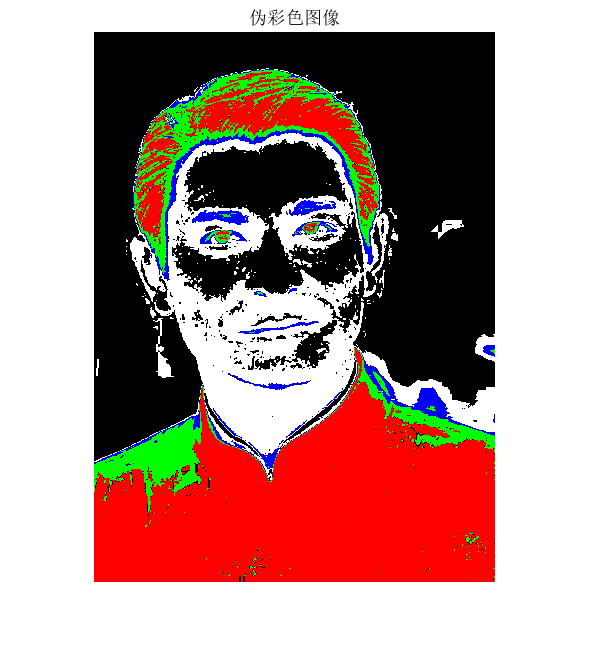

%对R通道数据进行灰度分层处理，生成5种颜色伪彩图像，自定义分层准则和伪彩色，显示伪彩色图像
%先提取原图r通道
im_r=image_o(:,:,1);
im_r=double(im_r)/255;


%分层处理

%建立新图像的三通道
imNew_r=zeros(size(im_r));
imNew_g=zeros(size(im_r));
imNew_b=zeros(size(im_r));

imNew_r(im_r<0.2)=1;%红色

imNew_g(0.2<im_r&im_r<0.4)=1;%绿色

imNew_b(0.4<im_r&im_r<0.6)=1;%蓝色


imNew_r(0.6<im_r&im_r<0.8)=1;%黑色
imNew_g(0.6<im_r&im_r<0.8)=1;
imNew_b(0.6<im_r&im_r<0.8)=1;

imNew_r(im_r>0.8)=0;%白色，其实这里不写也没关系
imNew_g(im_r>0.8)=0;
imNew_b(im_r>0.8)=0;

%合并三通道
imNew=cat(3,imNew_r,imNew_g,imNew_b);

figure;
imshow(imNew);
title("伪彩色图像");

function hsi = rgb2hsi(rgb) %rgb转为hsi的函数

rgb = im2double(rgb); 
r = rgb(:, :, 1); 
g = rgb(:, :, 2); 
b = rgb(:, :, 3); 
%转化的公式如下
num = 0.5*((r - g) + (r - b)); 
den = sqrt((r - g).^2 + (r - b).*(g - b)); 
theta = acos(num./(den + eps)); 
H = theta; 
H(b > g) = 2*pi - H(b > g); 
H = H/(2*pi); 

num = min(min(r, g), b); 
den = r + g + b; 
den(den == 0) = eps; 
S = 1 - 3.* num./den; 
H(S == 0) = 0; 
I = (r + g + b)/3;
%将结果合并为hsi图像
hsi = cat(3, H, S, I);
end